## 6. Compruebe mediante su modelo geométrico inverso la configuración del robot para las posturas de la herramienta halladas en el anterior laboratorio, tales como puntos de calibración.

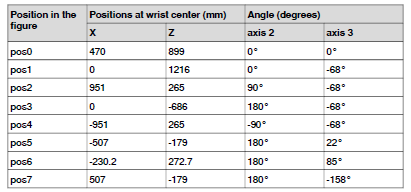

Es de considerar que los puntos de intersección dados por el fabricante solo se mueven las articulaciones 2 y 3, el resto se encuentran en posición inicial, en términos de pose no hay movimiento en Y: 

clc
syms theta_1 theta_2 theta_3 theta_4 theta_5 theta_6  
L1=0.265; L2=0.444; L3=0.110; L4=0.470; L5=0.080; L6=0.037;

%Se crean links, el primer parametro de la funcioón correspode al tipo de articulación. 
% En este caso todas son de tipo rotacional. Después se ingresan los
% parámetros alpha, a, d y offset. Luego se indica que los parametros
% corresponden a MDH. Finalmente se indican los rangos de operación.

L(1) = Link('revolute','alpha', 0,    'a', 0,   'd',L1,   'offset', 0,   'modified', 'qlim',[-pi pi]);
L(2) = Link('revolute','alpha', -pi/2,    'a', 0,   'd',0,   'offset', -pi/2,   'modified', 'qlim',[-pi pi]);
L(3) = Link('revolute','alpha', 0,    'a', L2,   'd',0,   'offset', 0,   'modified', 'qlim',[-3.92699 1.48353]);
L(4) = Link('revolute','alpha', -pi/2,    'a', L3,   'd',L4,   'offset', 0,   'modified', 'qlim',[-pi pi]);
L(5) = Link('revolute','alpha', pi/2,    'a', 0,   'd',0,   'offset', 0,   'modified', 'qlim',[-pi pi]);
L(6) = Link('revolute','alpha', -pi/2,    'a', L5,   'd',L6,   'offset', 0,   'modified', 'qlim',[-pi pi]);
% Se articulan todos los links y se le asigna un nombre a todo el sistema
Robot_ABB = SerialLink(L,'name','ABB CRB 15000'); 
%Se plotea el robot, para ciertos ángulos theta.

T_0_1=L(1).A(theta_1)

$$T\_0\_1 = \left(\begin{array}{cccc} \cos\left(\theta_{1}\right) & -\sin\left(\theta_{1}\right) & 0 & 0\\ \sin\left(\theta_{1}\right) & \cos\left(\theta_{1}\right) & 0 & 0\\ 0 & 0 & 1 & \frac{53}{200}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

%T_1_2=L(2).A(theta_2);
T_1_2=[cos(theta_2-pi/2) -sin(theta_2-pi/2) 0 0
    0 0 1 0
    -sin(theta_2-pi/2) -cos(theta_2-pi/2) 0 0
    0 0 0 1]

$$T\_1\_2 = \left(\begin{array}{cccc} \cos\left(\theta_{2}-\frac{\pi }{2}\right) & -\sin\left(\theta_{2}-\frac{\pi }{2}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ -\sin\left(\theta_{2}-\frac{\pi }{2}\right) & -\cos\left(\theta_{2}-\frac{\pi }{2}\right) & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T_2_3=L(3).A(theta_3)

$$T\_2\_3 = \left(\begin{array}{cccc} \cos\left(\theta_{3}\right) & -\sin\left(\theta_{3}\right) & 0 & \frac{111}{250}\\ \sin\left(\theta_{3}\right) & \cos\left(\theta_{3}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

%T_3_4=L(4).A(theta_4);
T_3_4=[cos(theta_4) -sin(theta_4) 0 11/100
    0 0 1 47/100
    -sin(theta_4) -cos(theta_4) 0 0
    0 0 0 1]

$$T\_3\_4 = \left(\begin{array}{cccc} \cos\left(\theta_{4}\right) & -\sin\left(\theta_{4}\right) & 0 & \frac{11}{100}\\ 0 & 0 & 1 & \frac{47}{100}\\ -\sin\left(\theta_{4}\right) & -\cos\left(\theta_{4}\right) & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

%T_4_5=L(5).A(theta_5);
T_4_5=[cos(theta_5) -sin(theta_5) 0 0
    0 0 -1 0
    sin(theta_5) cos(theta_5) 0 0
    0 0 0 1]

$$T\_4\_5 = \left(\begin{array}{cccc} \cos\left(\theta_{5}\right) & -\sin\left(\theta_{5}\right) & 0 & 0\\ 0 & 0 & -1 & 0\\ \sin\left(\theta_{5}\right) & \cos\left(\theta_{5}\right) & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

%T_5_6=L(6).A(theta_6);
T_5_6=[cos(theta_6) -sin(theta_6) 0 2/25
    0 0 1 37/1000
    -sin(theta_6) -cos(theta_6) 0 0
    0 0 0 1]

$$T\_5\_6 = \left(\begin{array}{cccc} \cos\left(\theta_{6}\right) & -\sin\left(\theta_{6}\right) & 0 & \frac{2}{25}\\ 0 & 0 & 1 & \frac{37}{1000}\\ -\sin\left(\theta_{6}\right) & -\cos\left(\theta_{6}\right) & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


TF = simplify(T_0_1*T_1_2*T_2_3*T_3_4*T_4_5*T_5_6);
TFF = subs(TF,[theta_1,theta_4,theta_5,theta_6],[0 0 0 0])

$$TFF = \left(\begin{array}{cccc} \cos\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)+\cos\left(\theta_{3}\right)\,\sin\left(\theta_{2}\right) & 0 & \cos\left(\theta_{2}+\theta_{3}\right) & \frac{111\,\sin\left(\theta_{2}\right)}{250}+\frac{507\,\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)}{1000}+\frac{19\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)}{100}+\frac{19\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{2}\right)}{100}-\frac{507\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)}{1000}\\ 0 & -1 & 0 & 0\\ \cos\left(\theta_{2}+\theta_{3}\right) & 0 & -\sin\left(\theta_{2}+\theta_{3}\right) & \frac{111\,\cos\left(\theta_{2}\right)}{250}+\frac{19\,\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)}{100}-\frac{507\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)}{1000}-\frac{507\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{2}\right)}{1000}-\frac{19\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)}{100}+\frac{53}{200}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Para la posición 0: x=470, z=899; articulaciones 2 y 3 = [0 0]

pose0 = [0.47 0 0.899 0 0 0]

pose0 =     0.4700         0    0.8990         0         0         0


Q0 = inversa(pose0)

Q0 =          0    0.1740   -0.1437         0   -0.2613    3.1416


TF0 = double(subs(TFF,[theta_2 theta_3],[0 0]))

TF0 =          0         0    1.0000    0.5070
         0   -1.0000         0         0
    1.0000         0         0    0.8990
         0         0         0    1.0000


TF_0 = double(subs(TF,[theta_1,theta_2,theta_3,theta_4,theta_5,theta_6],Q0))

TF_0 =     0.2290         0    0.9734    0.5677
         0    1.0000         0         0
   -0.9734         0    0.2290    0.8843
         0         0         0    1.0000


Para la posición 1: x=0, y=1216; articulaciones 2 y 3 = [0 -68°]

pose1 = [0 0 1.216 0 0 0]

pose1 =          0         0    1.2160         0         0         0


Q1 = inversa(pose1)

Q1 =          0   -0.3236   -0.5413         0    0.6339    3.1416


TF1 = double(subs(TFF,[theta_2 theta_3],[0 deg2rad(-68)]))

TF1 =    -0.9272         0    0.3746    0.0138
         0   -1.0000         0         0
    0.3746         0    0.9272    1.2503
         0         0         0    1.0000


TF_1 = double(subs(TF,[theta_1,theta_2,theta_3,theta_4,theta_5,theta_6],Q1))

TF_1 =     0.2290         0    0.9734    0.0977
         0    1.0000         0         0
   -0.9734         0    0.2290    1.2013
         0         0         0    1.0000


Para la posición 2: x=951, y=265; articulaciones 2 y 3 = [90° -68°]

pose2 = [0.951 0 0.265 0 0 0]

pose2 =     0.9510         0    0.2650         0         0         0


Q2 = inversa(pose2)

Q2 =          0    1.6684   -1.3409         0   -0.5586    3.1416


TF2 = double(subs(TFF,[theta_2 theta_3],[deg2rad(90) deg2rad(-68)]))

TF2 =     0.3746         0    0.9272    0.9853
         0   -1.0000         0         0
    0.9272         0   -0.3746    0.2512
         0         0         0    1.0000


TF_2 = double(subs(TF,[theta_1,theta_2,theta_3,theta_4,theta_5,theta_6],Q2))

TF_2 =     0.2290         0    0.9734    0.9400
         0    1.0000         0         0
   -0.9734         0    0.2290    0.2610
         0         0         0    1.0000


Para la posición 3: x=0, y=-686; articulaciones 2 y 3 = [180° -68°]

pose3 = [0 0 -0.686 0 0 0]

pose3 =          0         0   -0.6860         0         0         0


Q3 = inversa(pose3)

Q3 =          0    3.0657   -1.3409         0   -1.9558    3.1416


TF3 = double(subs(TFF,[theta_2 theta_3],[pi deg2rad(-68)]))

TF3 =     0.9272         0   -0.3746   -0.0138
         0   -1.0000         0         0
   -0.3746         0   -0.9272   -0.7203
         0         0         0    1.0000


TF_3 = double(subs(TF,[theta_1,theta_2,theta_3,theta_4,theta_5,theta_6],Q3))

TF_3 =     0.2290         0    0.9734    0.0880
         0    1.0000         0         0
   -0.9734         0    0.2290   -0.5727
         0         0         0    1.0000


Como se puede apreciar para las posiciones anteriores, el método no es efectivo para solucionar las posiciones de las articulaciones, esto debido a que se manejan múltiples condiciones de contorno y frontera, así como variables de valor negativo, para las cuales se deben realizar otras consideraciones las cuales no caben dentro del método analítico del robot, sino que requieren de comparaciones y manejo de cuadrantes.

function Q = inversa(pose)   %angulos en grados
syms theta_1 theta_2 theta_3 theta_4 theta_5 theta_6 
L1=0.265; L2=0.444; L3=0.110; L4=0.470; L5=0.080; L6=0.101; 
L(1) = Link('revolute','alpha', 0,    'a', 0,   'd',L1,   'offset', 0,   'modified', 'qlim',[-pi pi]);
L(2) = Link('revolute','alpha', -pi/2,    'a', 0,   'd',0,   'offset', -pi/2,   'modified', 'qlim',[-pi pi]);
L(3) = Link('revolute','alpha', 0,    'a', L2,   'd',0,   'offset', 0,   'modified', 'qlim',[-pi pi]);
L(4) = Link('revolute','alpha', -pi/2,    'a', L3,   'd',L4,   'offset', 0,   'modified', 'qlim',[-pi pi]);
L(5) = Link('revolute','alpha', pi/2,    'a', 0,   'd',0,   'offset', 0,   'modified', 'qlim',[-pi pi]);
L(6) = Link('revolute','alpha', -pi/2,    'a', L5,   'd',L6,   'offset', 0,   'modified', 'qlim',[-pi pi]);

pos_dada = [pose(1) pose(2) pose(3)];  %[0.522 0.522 0.864]; % Pos. Final Pedida
ori_dada = [pose(4) pose(5) pose(6)]*pi/180; %[-30.326 26.760 -44.822]*pi/180; % Ori. Final Pedida

% pos_dada = [0.498 0.7733 0.234]; % Pos. Final Pedida
% ori_dada = [178.103 -1.289 -55.821]*pi/180; % Ori. Final Pedida
% pos_dada = [0.744 0.379 0.680]; % Pos. Final Pedida
% ori_dada = [-154.184 40.52 46.130]*pi/180; % Ori. Final Pedida

q1 = atan2(pos_dada(2),pos_dada(1));

T_06 = transl(pos_dada)*rpy2tr(ori_dada);
m = (T_06*[0 0 1 1]')';
m(:,4) = [];
P = m-pos_dada;
phi_1 = atan2(P(3),sqrt(P(1)^2+P(2)^2));
%phi_1 = acos(-0.9992);
f = atan2(L5,L6);
h= phi_1+f;
P_65 = [cos(q1)*(cos(h)*sqrt(L5^2+L6^2)) sin(q1)*(cos(h)*sqrt(L5^2+L6^2)) sin(h)*sqrt(L5^2+L6^2)]; %P_65 = [-L5 0 -L6]; 
P_05 = pos_dada-P_65;
P_01 = [0 0 L1]; P_06 = pos_dada;
% 
% P_05 = P_06+P_65; %P_05 = (T_06*[P_65 1]')';
%P_05(:,4) = [];
P_15 = P_05-P_01;
a = P_15(1); b = P_15(2); c = P_15(3); 

sigma = atan2(L4,L3);
alpha = acos((-a^2-b^2-c^2+(L2^2+L3^2+L4^2))/(2*L2*sqrt(L3^2+L4^2)));
q3 = pi-sigma-alpha;

beta = atan2(c,sqrt(a^2+b^2));
gamma = acos((L2^2-L3^2-L4^2+a^2+b^2+c^2)/(2*L2*sqrt(a^2+b^2+c^2)));
q2 = pi/2-beta-gamma;

P_56_a = [cos(q1)*L6 sin(q1)*L6 L5];
ang_0 = atan2(P_65(3),sqrt(P_65(1)^2+P_65(2)^2));
ang_1 = atan2(P_56_a(3),sqrt(P_56_a(1)^2+P_56_a(2)^2));

q5 = -q2-q3+ang_1-ang_0;

%---------------------------
T_01 = L(1).A(q1);
T_12 = L(2).A(q2);
T_23 = L(3).A(q3);
T_34 = L(4).A(0);
T_45 = L(5).A(q5);
q6 = 0;
T_56 = L(6).A(q6);
T_06 = real(T_01*T_12*T_23*T_34*T_45*T_56);
RPY = tr2rpy(T_06);
q6 = -RPY(3)+ori_dada(3);


Q = real([q1 q2 q3 0 q5 q6]);
end
